# Create and Use a Custom Finder

The MATLAB Report Generator report generation API supports creation of finders that search data containers for specified objects and return the results in reportable form. Finders allow you to separate search logic from report logic in your report generators. Finders also promote reuse of search logic, thereby speeding development of report generators. This example shows how to develop and use a finder to generate a report.

## Define a Finder

Creating a finder entails creating a MATLAB class that defines the finder's properties and behavior. The following sections explain the steps needed to create a finder class. The explanation uses  a class named `GrantFinder as an example`. The code for the class resides in a file, `GrantFinder.m`, that accompanies this script. The `GrantFinder` class defines a finder capable of finding and formatting grants awarded by the U.S. National Endowment for the Humanities (NEH). 

**Create a Skeleton Class Definition File**

Use the **MATLAB Editor** (not the **Live Editor**) to create a skeleton class definition for your finder, for example

**Specify Finder Base Class**

Specify the Report API's `mlreportgen.finder.Finder` class as the base class for your finder.

This base class defines properties that are common to finders, including

- `Container`: a property used to reference the container to be searched by the finder. For example, the `GrantFinder` use this property to store a reference to a grant database that it creates.

- `Properties`: a property used by finder clients to specify property values that an object must have to satisfy a search. For example, this property allows a GrantFinder client to specify the grant properties that a a grant must have to be returned as a result of a search of the NEH grant database.

The `mlreportgen.finder.Finder` class specifies other properties and methods that your finder class definition must define. This ensures that your finder works with the Report API.

**Define a Finder Constructor**

Define a function that creates an instance of your finder, for example,

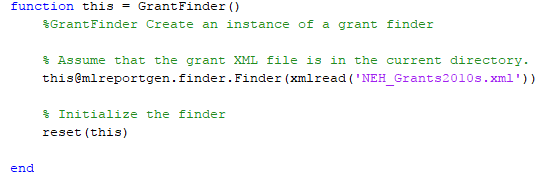

The `GrantFinder` constructor uses MATLAB's `xmlread` function to read the grant XML file from disk and convert it to a Java DOM document. It then passes the DOM document to the `mlreportgen.finder.Finder` constructor, which sets the Java DOM document as the value of the finder's `Container` property. Storing the NEH database as a Java DOM document allows the finder to use third-party Java software to search the data base. See [Xerces Java DOM API](https://xerces.apache.org/xerces2-j/javadocs/api/org/w3c/dom/package-summary.html) for more information.

The constructor also calls a  `reset` function that initializes variables used to search the grant database. The GrantFinder class defines this function. Similarly, your class  must define a reset function. The `reset` function ensures that a client can use your finder to conduct multiple searches of its container. See **Define a Reset Function** for more information.

**Define a **`find`** Method**

Define a method to search the finder container for objects that meet user-specified constraints. The find method must return an array of result objects that contain the objects that it finds. Result objects are objects of base type `mlreportgen.finder.Result`. Returning the find results as  result objects allows a user of your finder to add the results to a report or report chapter. See **Define a Finder Result** for more information. Returning the find results as a MATLAB array allows you to use for loop to process search results, for example

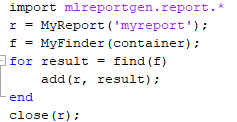

The `GrantFinder`'s `find` method illustrates definition of a `find` method.

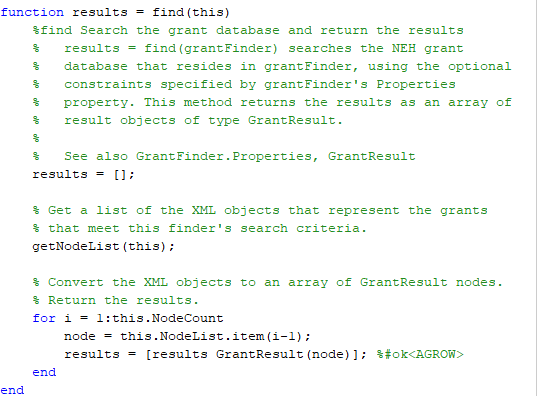

This find method uses `getNodeList`, a search utility function that the `GrantFinder` class defines (see **Define a Search Utility Method**) to search the grant database for grants that meet property value constraints specified by the finder's `Properties` property. The `getNodeList` function sets an internal property named `NodeList` to the result of its search. The result is a Java DOM `NodeList` object ([`NodeList`](https://xerces.apache.org/xerces2-j/javadocs/api/org/w3c/dom/NodeList.html)) that contains the search results as a list of Java DOM elements ([`Element`](https://xerces.apache.org/xerces2-j/javadocs/api/org/w3c/dom/Element.html)).

The `find` method then converts this node list to an array of result objects of type `GrantResult`. It uses the `GrantResult` constructor to create a grant result object from the Java DOM `Element` object that contains the grant data.

**Define**` hasNext`** and **`next`** Methods**

Your finder class definition must define `hasNext` and `next` methods. On its first invocation, your `hasNext` method must create a queue of search results and return true if the queue is not empty. On subsequent invocations the `hasNext` method must return `true` if the queue is empty, `false` otherwise. Your `next` method must return the first result in the queue on its first invocation, the next result, on its next invocation, and so on, until the queue is empty.

These methods are intended to allow a client of your finder to use a MATLAB `while` loop to search your finder's container, for example,

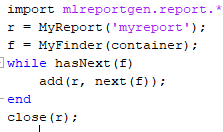

The `GrantFinder` class illustrates a `hasNext` method.

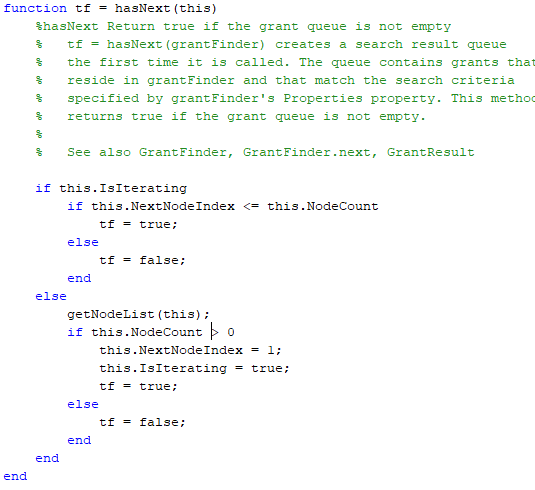

This method first checks whether it has already created a search queue as indicated by the finder's `IsIterating` property. If the queue already exists and is not empty, this method returns `true`. if the queue exists and is empty, this method returns `false`. If the queue does not yet exist (i.e., this is the method's first invocation), the `hasNext` method creates a result queue as follows. First, it uses its internal `getNodeList` method to get the grants that meet the search criteria specified by the finder's `Properties` property. The `getNodeList` method sets an internal finder property named `NodeCount` to the number of results found. If `NodeCount` is greater than zero, the `hasNext` method sets an internal property named `NextNodeIndex` to 1. The finder's `next` method uses this property to save the state of the search queue, that is the next item in the queue. Finally, if the queue is not initially empty, the finder returns `true`; otherwise, `false`.

The `GrantFinder`'s `next` method operates on the queue created by the `hasNext` method.

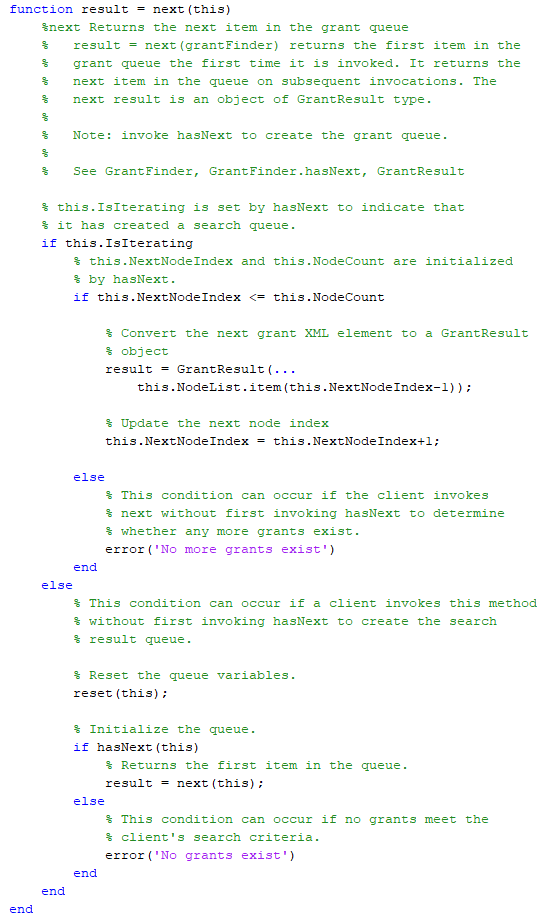

**Define a Search Utility Method**

Your finder's `find` and `hasNext` methods must search your finder's container for objects that satisfy search constraints. You should consider defining a search utility that both methods can use. For example, the `GrantFinder` `hasNext` and `next` methods both delegate searching to an internal utility named `getNodeList`. The `getNodeList` method in turn delegates searching to an XML document search API named `XPath` (see [XPath Tutorial](https://www.w3schools.com/xml/xpath_intro.asp)).

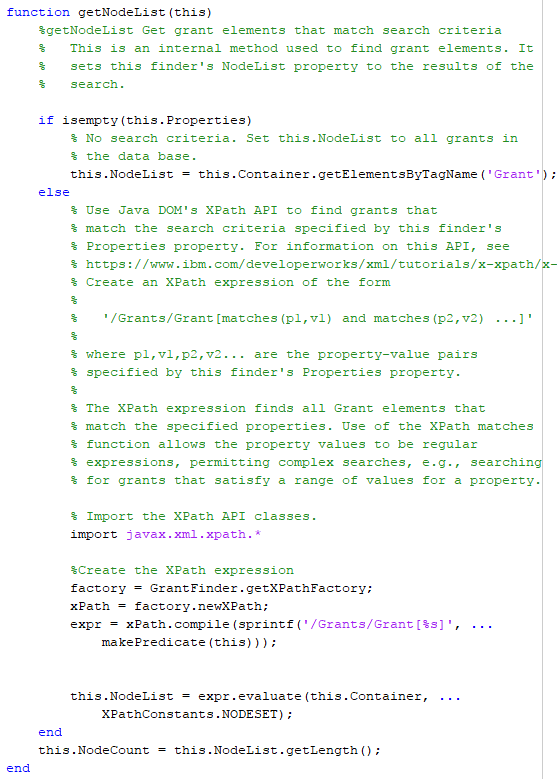

**Create an **`InvalidPropertyNames`** Property**

Your finder must define a property named `InvalidPropertyNames` that specifies object properties that cannot be used to constrain a search. The `mlreportgen.finder.Finder` base class uses this property to verify that user-specified search properties specified by your finder's `Properties` property are valid. If not, the base class throws an error. In other words, if a client sets your finder's `Properties` property to invalid properties, the base class throws an error. In this way, the Report API's base finder handles property validity checking for your finder.

If your finder can use any search object property as a search constraint, it should set the `InvalidPropertyNames` property empty. For example, the `GrantFinder` can handle any grant property. It therefore sets this property empty:

**Define a **`reset`** Method**

A finder must be able to support multiple searches to avoid the need to create a finder for every search. For this reason, the Report API's base finder class forces your finder class to define a `reset` method that resets variables used by your finder's search logic, for example,

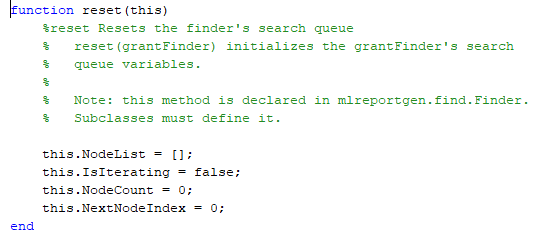

## Define a Finder Result

If a suitable definition does not exist, you must create a class to define the result objects returned by your finder. This section shows how to define a finder result object. It uses a class named `GrantResult` as an example. The `GrantResult` class defines results returned by the `GrantFinder` class used as an example in the **Define a Finder** section. The `GrantResult.m` file that accompanies this script contains the code for the `GrantResult` class. Defining a finder result entails the following tasks.

**Specify the Result Base Class**

Define `mlreportgen.finder.Result` as the base class for your result class, for example,

**Define **`Object `**Property**

Define a property named `Object` that clients of your result object can use to access the found object that your result object  contains. Specify `protected` as the `SetAccess` value of your finder's `Object` property. This ensures that only your result can specify the found object that it contains.

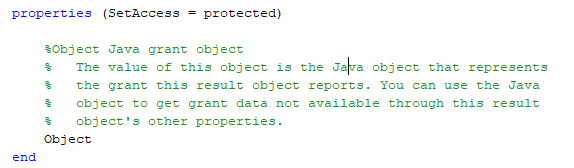

Your result constructor must set the found object as the value of its `Object` property. Your result constructor can use the base class constructor to perform this task, for example, 

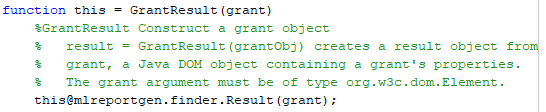

**Expose Found Object Properties**

Your result's `Object` property allows a client to access the found object and therefore its properties. However, accessing the properties can requires extra code or specialized knowledge. You may want to expose some or all of the found object's properties as properties of the result object. For example, the `GrantResult` class exposes the following subset of a grant's properties.

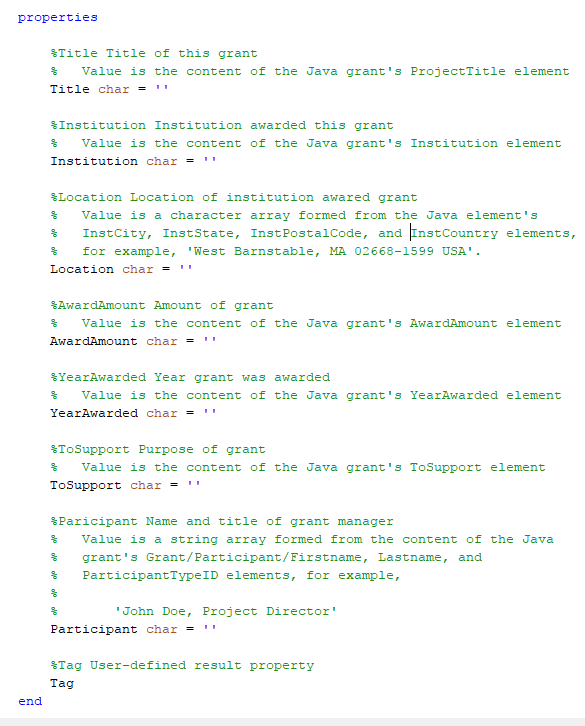

This saves the client of the grant finder result object from having to extract these properties itself. Your result's constructor should extract the values of the properties to be exposed and set the corresponding result properties to the extracted values, for example,

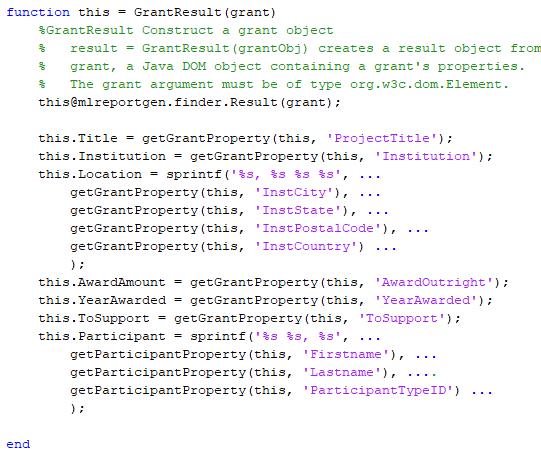

Note that `GrantResult` combines some of the grant properties into a single exposed property. For example, it exposes a grant's `InstCity`, `InstState`, `InstPostalCode`, and `InstCountry` properties into a single result property named `Location`.

In this example, the constructor uses internal methods to extract the grant properties from the grant object, which is a Java DOM `Element` object, for example,

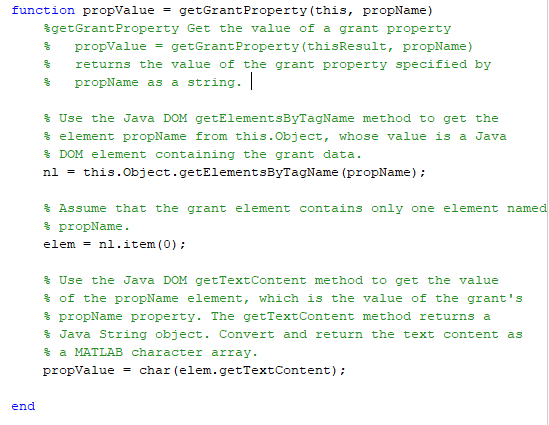

**Define a **`getReporter`** Method**

You must define a getReporter method for your result object that returns a reporter object that reports on the found object that the result object contains. This method allows a client of your finder to report on a result of a find operation simply by adding the result to a `Report`, `Section`, or `Chapter` object. For example,

A report or chapter's `add` method knows that a result object must have a `getReporter` method that returns a reporter that formats the data the result contains. So if you add a result object to a report or chapter, the `add` method invokes the result's `getReporter` method to get the result reporter and adds the result reporter to the report or reporter, causing the result data to be formatted and included in the report.

The `GrantResult` class definition defines a `getReporter` method that returns a customized version of the Report API's `mlreportgen.report.BaseTable` reporter. The `BaseTable` reporter generates a table with a numbered title. The `GrantResult` class customizes the `BaseTable` reporter to generate a table of grant properties, for example,

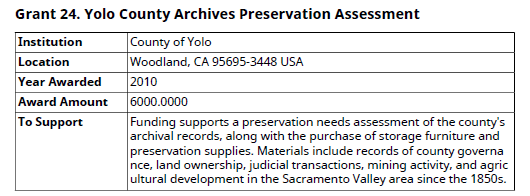

The following code shows how the `GrantResult` class customizes the `BaseReporter` to generate a numbered grant properties table:

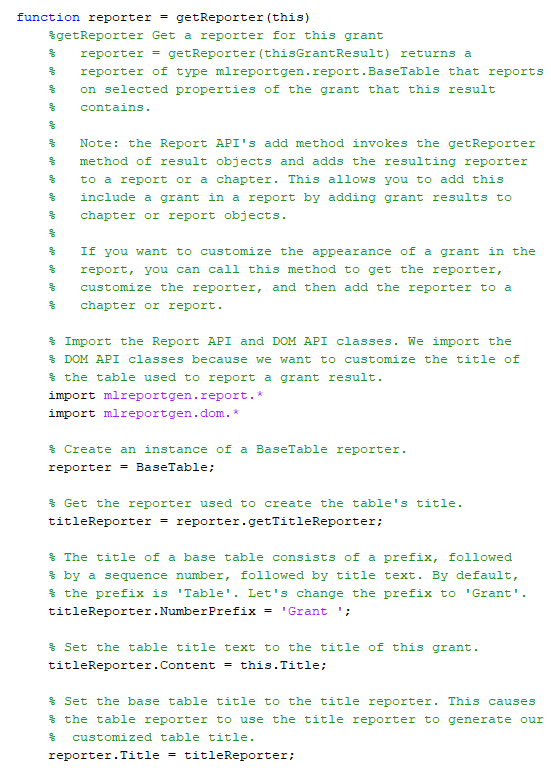

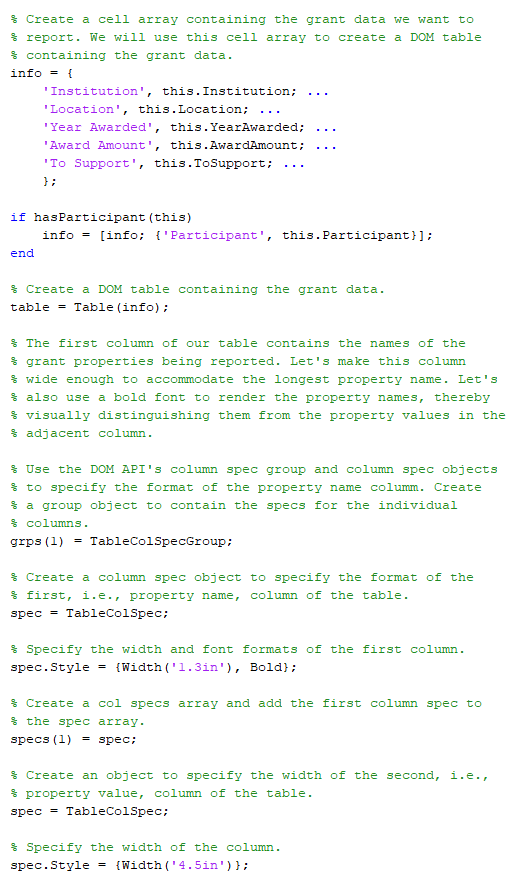

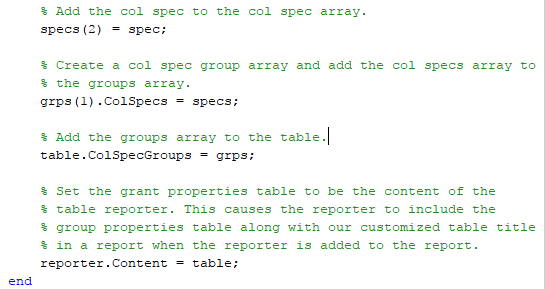        

## Use a Finder

This script shows how to use  a finder to generate a report. This script uses the GrantFinder example used in the Define a Finder section to generate a PDF report on NEH grants to institutions in selected states from 2010 through 2012. The script performs the following tasks.

**Import the Report Generator API**

Import the classes included in the MATLAB Report Generator's Report API. Importing the classes allows the script to use unqualified (i.e., abbreviated) names to refer to the classes.

import mlreportgen.report.*
import mlreportgen.dom.*

**Create a Report Container**

Create a PDF container for the report, using the Report API's `mlreportgen.report.Report` class. Note that because the script imports the Report API, it can refer to the class by its unqualified name.

rpt = Report('grant', 'pdf');


**Create the Report Title Page**

Add a title page to the report, using the Report API's `TitlePage` class.

add(rpt, TitlePage( ...
    'Title', 'NEH Grants', ...
    'Subtitle', 'By State from 2010-2012', ...
     'Image', 'neh_logo.jpg', ...
     'Author',  'John Doe' ...
    ));

**Create the Report Table of Contents**

Add a table of contents, using the Report API's `TableOfContents` class.

add(rpt, TableOfContents);


**Find the Report Data**

Use an array of structures to specify the states to be included in this report. Each structure contains the data for a specific state:

- `Name`: name of the state

- `PostalCode`: the state's postal (zip) code

- `Grants`: grants made to institutions in the state. This field is initially empty.

- `NGrants`: number of grants made to institutions in this state (initially empty)

states = struct( ...
    'Name', {'California', 'Massachusetts', 'New York'}, ...
    'PostalCode', {'CA', 'MA', 'NY'}, ...
    'Grants', cell(1,3), ...
    'NGrants', cell(1,3) ...
    );


Use a grant finder to populate the `Grants` and `NGrants` fields of the state structures. Create the grant finder.

f = GrantFinder;

Loop through the state array. For each state, use  the finder's `Properties` property to constrain the search for grants awarded to the state. Use these grant properties to constrain the search:

- `InstState`: Specifies the postal code of the state in which the institution that received the grant is located.

- `YearAwarded`: Specifies the year in which the grant was awarded.

The finder treats property values as regular expressions. Exploit this fact to specify a range of values, 2010-2012, as the value of the `YearAwarded` property.

n = numel(states);
for i = 1:n    
    f.Properties = [
        {'InstState', states(i).PostalCode}, ...       
        {'YearAwarded', '201[0-2]'}];
    states(i).Grants = find(f);
    states(i).NGrants = numel(states(i).Grants);
end

**Create the Grant Summary Chapter**

Create a grant summary as the first chapter of the report. The grant summary chapter contains a title and a grant summary table. Each row of the table lists the total number of grants and total amount of money awarded to institutions in the state for the years 2010-2012. States appear in the table in descending order of number of grants. Each state is hyperlinked to the chapter that details the grants awarded to it. 

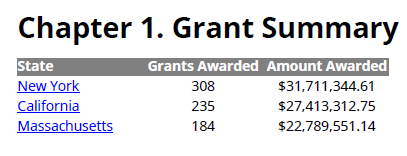

**Create the Summary Chapter Container**

Start by creating a chapter container. .

ch = Chapter('Title', 'Grant Summary');

**Create the Contents of the Grant Summary Table**

Start by creating a Java currency formatter. Use this object to format the dollar amount of the grants awarded to a state.

currencyFormatter = java.text.NumberFormat.getCurrencyInstance();

Create a cell array containing the contents of the table header.

header = {'State', 'Grants Awarded', 'Amount Awarded'};

Preallocate a cell array to contain the table body contents. The cell array has Rx3 rows and columns where R is the number of states and 3 is the number of summary items reported for each state. 

body = cell(numel(states), 3);

Sort the states array by the number of grants awarded to them, using the MATLAB `sort` function. The `sort` function returns `ind`, an array of indices to the states array.  The first index of the `ind` array is the index of the state with the most grants, the second, with the second most number of grants, etc. 

[~, ind] = sort([states.NGrants], 'descend');

Loop through the states by number of grants, filling in the summary information for each state. Use a variable, `rowIdx`, as an index to the cell array row corresponding to the current state.

rowIdx = 0;

The following line rearranges the `states` array in order of grants received and creates a `for` loop that assigns each structure in the sorted `states` array to the variable `state` on each iteration of the loop.

for state = states(ind)

Update the row index to point to the cell array row corresponding to the current state.

    rowIdx = rowIdx+1; 

The script enters a hyperlink to the grant details chapter for the state as the first entry in the table for the state, for example, 

The following line uses a DOM `InternalLink` constructor to create the hyperlink. The `InternalLink` constructor takes two arguments, a link target id and the text of the hyperlink. The script uses the current state's postal code as the link target id and the state's name as the link text. Later on, when the script creates the grant details chapter, it inserts a link target in the chapter title whose id is the state's postal code. This completes creation of the hyperlink.

    body(rowIdx, 1) = {InternalLink(state.PostalCode, state.Name)};

Assign the total number of grants for this state to the second item in its cell array row.

    body(rowIdx, 2) = {state.NGrants};
    

Compute the total amount awarded to this state.

    totalAwarded = 0;
    for grant = state.Grants
        totalAwarded = totalAwarded + str2double(grant.AwardAmount);
    end
    

Use the currency formatter to format the total amount as a dollar amount, for example,

and assign the formatted result as the third and final item in the cell array for this state.

    body(rowIdx,3) = {char(currencyFormatter.format(totalAwarded))};
end

To create the summary table, pass the header and body cell arrays to the constructor of a `mlreportgen.dom.FormalTable` object.

table = FormalTable(header, body);

A formal table is a table that has a header and a body. The `FormalTable` constructor takes two arguments: a cell array that specifies the contents of the table's header and a cell array that  specifies the contents of its body. The constructor converts the cell array contents to DOM `TableRow` and `TableEntry` objects that define the table, saving the script from having to create the necessary table objects itself. 

**Format the Grant Summary Table**

At this point, the summary table looks like this:

This is not very readable. The heading has the same format as the body and the columns are not spaced apart.

In the following steps, the script adjusts the header text formatting to look like this:

First the script specifies the width and alignment of the table columns, using a DOM `TableColSpecGroup` object. A `TableColSpecGroup` object specifies the format of a group of columns. The summary table has only one group of columns so the script needs to create only one `TableColSpecGroup` object.

grp = TableColSpecGroup;

The `TableColSpecGroup` object lets the script specify the default style of the table's columns. The script specifies `1.5in` as the default width of the columns and center alignment as the default column alignment. 

grp.Style = {HAlign('center'), Width('1.5in')};

The script uses a `TableColSpec` object to override the default column alignment for the first column.

specs(1) = TableColSpec;
specs(1).Style = {HAlign('left')};
grp.ColSpecs = specs;
table.ColSpecGroups = grp;

**Note** The script could use as many as three `TableColSpec` objects, one for each table column, to override the group column styles. The first `TableColSpec` object applies to the first column, the second to the second column, etc. The script needs to assign only one column spec object to the group because it is overriding the default style only for the first column. However, if it needed to change only the third column, it would have to assign three column spec objects, leaving the `Style` property of the first two column spec objects empty.

The default table style crowds the table entries. So the script uses a DOM `InnerMargin` format object to create some space above the entries to separate them from the entries in the row above them. An `InnerMargin` object creates space (inner margin) between a document object and the object that contains it, for example, between the text in a table entry and the table entry's borders. The `InnerMargin` constructor optionally takes four arguments, the left, right, top, bottom inner margins of a document object.

The script use this constructor to create a top inner margin format of 3 points. It then assigns this format to the style of the entries in the summary table's body section.

table.Body.TableEntriesStyle = {InnerMargin('0pt', '0pt', '3pt', '0pt')};

Finally the script format the table header to consist of bold, white text on a gray background:

table.Header.row(1).Style = {Bold, Color('white'), BackgroundColor('gray')}; 

**Add the Summary  Chapter to the Report**

add(ch, table);

add(rpt, ch);

**Create the Grant Details Chapters**

Loop through the state structures.

for state = states
    

For each state create a chapter to hold the state's grant details. Insert a link target into the chapter title to serve as a target for the hyperlink in the summary table in the first chapter.

    ch = Chapter('Title', {LinkTarget(state.PostalCode), state.Name});
    

Loop through the grant results for the state.

    for grant = state.Grants
        

For each grant result, add the result to the chapter.

        add(ch, grant);

A grant result has a `getReporter` method that returns  a reporter that creates a table of selected grant properties. The chapter `add` method is preconfigured to get a result's reporter and add it the chapter. Thus, adding a grant to a chapter is tantamount to adding the result property table  to the chapter, for example,

    end
    add(rpt, ch);
end  

**Close the Report Object**

Closing the report object generates the PDF output file (`grant.pdf`) that the report object specifies.

close(rpt);

**Display the report**

rptview(rpt);

## Appendix: The NEH Grant Database

The source of the database used in this example is the National Endowment for the Humanities (NEH). The database contains information on NEH grants for the period 2010-2019. It contains about 6000 records in XML format. It is available at [NEH Grant Data](https://catalog.data.gov/dataset/neh-grant-data-2010-2019). This example uses a local copy of the database XML file, `NEH_Grants2010s.xml`.

The database consists of a `Grants` element that contains a set of `Grant` elements each of which contains a set of grant data elements. The following is an extract from the database that illustrates its structure:

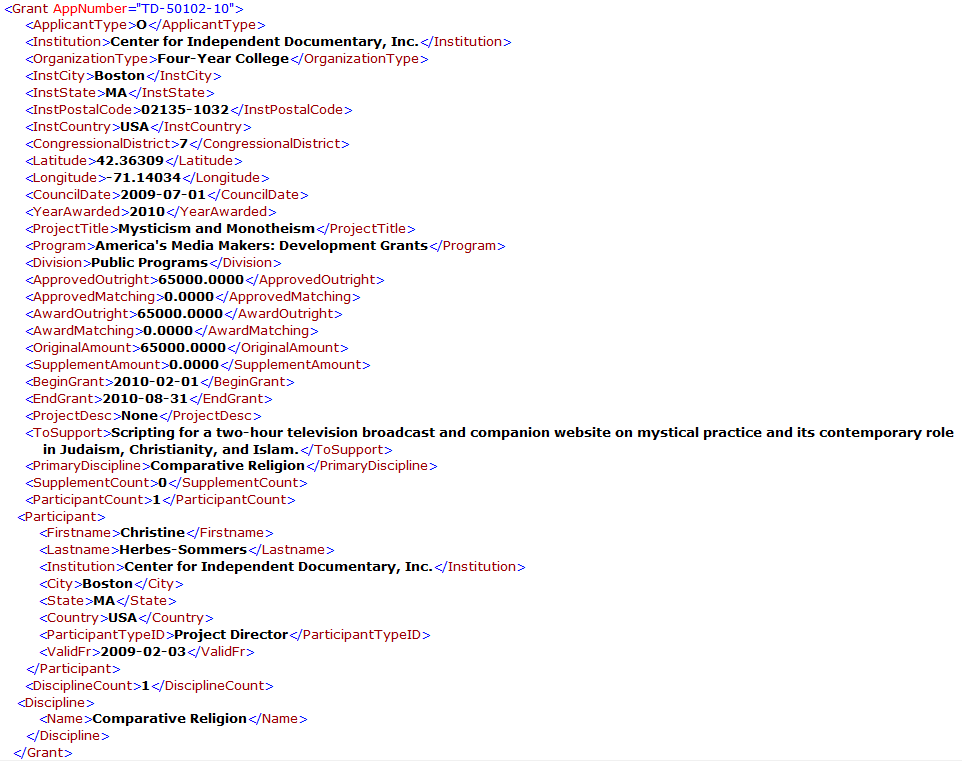

*Copyright 2012 The MathWorks, Inc.*